clear all
close all
clc

Second deliverable of assignment 2

Engine parameters given:

mc = 23.81; %corrected mass flow rate
h = 0; %Altitude (in feet)
M0 = 0; %Flight Mach
g_a = 1.4; %Specific Heat Ratio for air
g_gas = 1.33; %Specific Heat Ratio for exhaust gases
cp_a = 1000; %Constant Pressure Specific Heat for air
cp_gas = 1150; %Constant Pressure Specific Heat for exhaust gases
R = 287; %Specific Gas Constant (AIR)
h = 0.3048*h;
[P0, T0, rho0] = ISA(h);
At_An = 0.5184; % using At/An from A2_1
%T4t = 1159.2; % Get T4
T4t = 900; % Get T4
A8true = 0.0705;
A4true = At_An*A8true;

Efficiencies:

eta_comp = 0.9; %Isentropic efficiency of the Compressor
eta_tur = 0.9; %Isentropic efficiency of the turbine

Intake:

T0t = T0*(1 + ((g_a-1)/2)*M0^2);
P0t = P0*(1 + ((g_a-1)/2)*M0^2)^(g_a/(g_a-1));
T2t = T0t;
P2t = P0t;

% mtrue = mc*(P0t/P0)/sqrt(T0t/T0)
MT = linspace(0.1,1,10);
MT = 1;
MN = linspace(0.1,1,10);
% MN = 1;
valid = 1;

for i = 1:length(MT)
    for j = 1:length(MN)

        M4p = MT(i);
        M8p = MN(j);
        
        mcor4p = fun2(M4p,g_gas);
        mcor8p = fun2(M8p,g_gas);
        

%         TR = linspace(0,1);   %Temperature Ratio in the turbine T5t/T4t
%         plot(TR, TR - ((mcor8p/(mcor4p*At_An))^2)*(1 - (1/eta_tur).*(1 - TR)).^(2*g_gas/(g_gas-1)))
%         grid minor
%         TR = 0.5;
%         for n = 1:10000
%             TR = 1 - ((1 - (mcor4p*At_An/mcor8p)*TR^((g_gas-1)/(2*g_gas)))*eta_tur); 
%         end
%         TR = 0.5
%         TR - (mcor8p/(mcor4p*At_An))*(1 - (1/eta_tur)*(1 - TR))^(2*g_gas/(g_gas-1))
%         TR = 1
%         TR - (mcor8p/(mcor4p*At_An))*(1 - (1/eta_tur).*(1 - TR)).^(2*g_gas/(g_gas-1))
%         TR = fzero(@(TR) TR - (mcor8p/(mcor4p*At_An))*(1 - (1/eta_tur).*(1 - TR)).^(2*g_gas/(g_gas-1)), [0.2,1])
        
        step = 10^-5;
        TR = 0.2;
        TR_1 = 1;
        while TR_1 > 0
            TR_1 = TR - ((mcor8p/(mcor4p*At_An))^2)*(1 - (1/eta_tur).*(1 - TR)).^(2*g_gas/(g_gas-1));
            TR = TR + step;
        end

        OPR = (1 + eta_comp*(cp_gas/cp_a)*(T4t/T2t)*(1-TR))^(g_a/(g_a-1));
        
        P3t = P2t*OPR;
        T3t = T2t*(1 + (1/eta_comp)*(OPR^((g_a-1)/g_a) - 1));
        W_cspec = cp_a*(T3t-T2t);
        LHV = 43000000; % Lower Heating Value (Kerosene = 43MJ/kg)
        P4t = P3t;
        m_fspec = (cp_gas*(T4t-T3t))/(LHV);
        W_tspec = W_cspec;
        T5t = T4t - W_tspec/(cp_gas);
        T5tcheck = T4t*TR;
        P5t = P4t * ((1 - (1/eta_tur)*(1 - T5t/T4t))^(g_gas/(g_gas - 1)));
        pr_crit = (1 - ((g_gas - 1) / (g_gas + 1)))^(-g_gas / (g_gas - 1));
        pr_true = (P5t/P0);
        if pr_true > pr_crit
            choked = true;
        else
            choked = false;
        end

        if choked
            
            P8 = P5t/pr_crit;
            M8 = 1;
            
            mcorr8check = fun2(M8,g_gas);
            mcorr4check = mcorr8check*(((P5t/P4t)*sqrt(T4t/T5t))/(At_An));
            
            %here I impose the equality of the compressor area, without
            %knowing it

            m = mc*(mcorr4check/1.3503)*(P2t/101325)*(OPR/5.5)*sqrt(1159.2/T4t);

            M4 = 0;
            for n = 1:10000
                M4 = ((mcorr4check*sqrt(g_gas-1))/(g_gas))/((1 + ((g_gas-1)/2)*M4^2)^((g_gas+1)/(2-2*g_gas)));
            end

            if M4 > 1
                M4 = 1;
            end

            T8t = T5t; %assuming adiabatic flow
            T8 = T8t/((g_gas+1)/2);

            A4 = m*sqrt(cp_gas*T4t)/(mcorr4check*P4t);
            A8 = m*sqrt(cp_gas*T5t)/(mcorr8check*P5t);

        else
            P8 = P0;
            T8t = T5t;
            T8 = T8t*(1 - (1- (P8/P5t)^((g_gas-1)/g_gas)));
            M8 = sqrt((T8t/T8 -1)*(2/(g_gas-1)));
            vjet = M8*sqrt(g_gas*R*T8);
            r8 = P8/(R*T8);
            mcorr8check = fun2(M8,g_gas);
            mcorr4check = mcorr8check*(((P5t/P4t)*sqrt(T4t/T5t))/(At_An));

            m = mc*(mcorr4check/1.3503)*(P2t/101325)*(OPR/5.5)*sqrt(1159.2/T4t);
            A8 = m*sqrt(cp_gas*T5t)/(mcorr8check*P5t);
            A4 = m*sqrt(cp_gas*T4t)/(mcorr4check*P4t);

            M4 = 0;
            for n = 1:10000
                M4 = ((mcorr4check*sqrt(g_gas-1))/(g_gas))/((1 + ((g_gas-1)/2)*M4^2)^((g_gas+1)/(2-2*g_gas)));
            end

            if M4 > 1
                M4 = 1;
            end
            
        end
        
        if (abs(M4-M4p)<1e-2) && (abs(M8-M8p)<1e-2) && (abs(A8-A8true)/A8true<1e-3) && (abs(A4-A4true)/A4true<1e-3) 
            M4
            M8
            m
            OPRplot(valid) = OPR
            mcorr2(valid) = mcorr4check*OPR*sqrt(cp_a*T2t/(cp_gas*T4t))
            valid = valid + 1;
        end

    end
end

M4 = 1

M8 = 1

m = 19.7099

OPRplot = 4.0114

mcorr2 = 2.8582

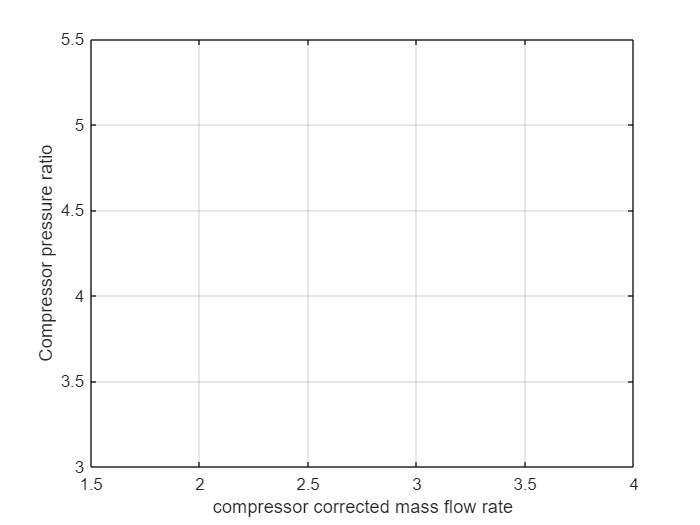


plot(mcorr2,OPRplot)
xlabel("compressor corrected mass flow rate")
ylabel("Compressor pressure ratio")
grid("on")

Thrust computation:

% T8 = T5t * (2 / (g_gas + 1));
% P8 = P5t / pr_crit;
% v_jet = sqrt(g_gas * R * T8);
% rho8 = P8 / (R * T8);
% A8 = (m / (rho8 * v_jet));
% F = m * (v_jet) + A8 * (P8 - P0)


function mcor = fun2(M,g)
mcor = M * (g/sqrt(g-1))*(1 + ((g-1)/2)*M^2)^((-g-1)/(2*g-2));
end
